# Image Thresholding 

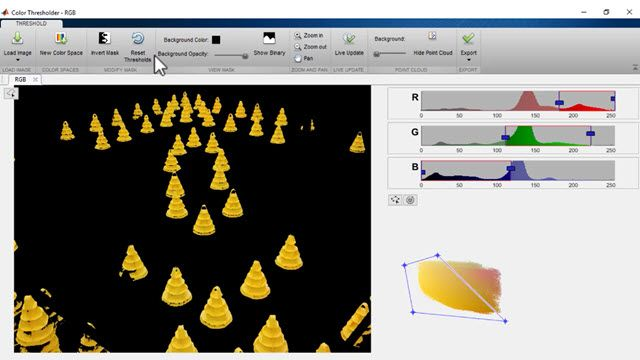

## Part A: Introduction

You can import an image into memory and assign it to a variable in the MATLAB workspace for later manipulation, display, and export. The file names don't necessarily indicate what an image file represents, but you can find out by displaying the image. You save image data to a variable using the `imread` function. Image data stored in variable `A` can be displayed using the `imshow` function.  You often want to view multiple images. For example, you might want to compare an image and a modified version of that image. The `"montage"` option places the images `A1` and `A2` side by side, with `A1` on the left and `A2` on the right.

**Instructions:**   imgFile1 is being read and saved to the variable A1 and shown. Try saving imgFile2 to A2 and then show the variable. After this, modify the imshowpair code to show both images at the same time and note down the differences between the two images!

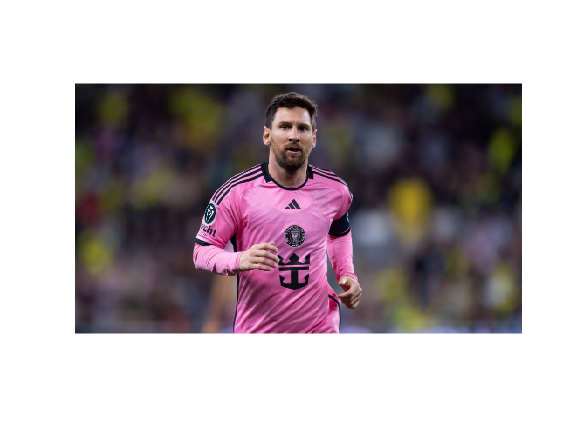

A1 = imread("/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/imgFile1.jpg");
imshow(A1)

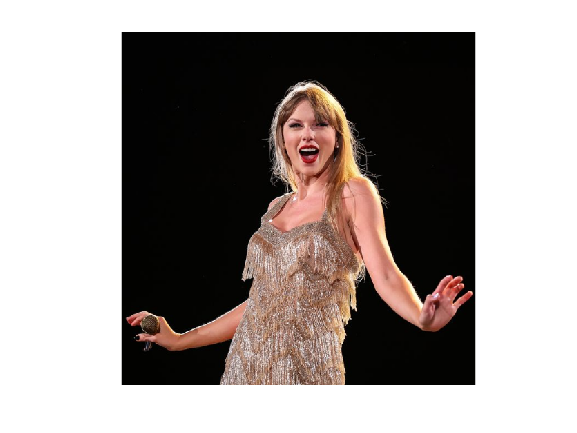


A2 = imread("/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/imgFile2.jpg");
imshow(A2)

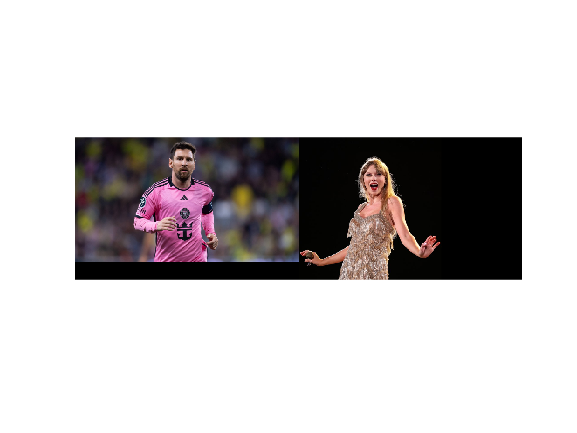


imshowpair(A1,A2,"montage")

Many image processing techniques are affected by image size. For example, when you displayed both images, you may have seen that the first image is smaller than the second.  You can find the size of an array by using the `size` function. The `size` function returns a vector. The first element in the vector is the number of rows in the array, which corresponds to the height of the image. The second element is the number of columns in the array, which corresponds to the width of the image.

**Instructions: **Save imgFile2 and view its size.

size1 = size(A1)

size1 =          560        1002           3


size2 = size(A2)

size2 =    639   640     3


Pixels are the smallest physical point in a digital image.  RGB (red, green, and blue) is the colorspace used to store images.  Every pixel's color is defined by an intensity of red, blue, and green color and that intensity ranges from 0 (devoid of light) to 255 (full brightness of color)  To declare an image use the following syntax:

%variable = uint8(zeros(height, width, color));

To save the image with a given file name, use the following syntax:

%imwrite(variable, filename);

**Instructions: **Write a program to draw the French Flag (The first column is blue, the second is white, and the third is red) 

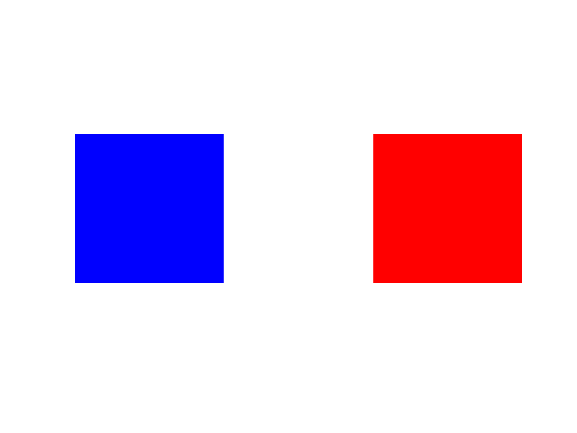

pix = uint8(zeros(300,900,3));

pix(:, 1:300, 3)=255;
pix(:, 301:600, :)= 255;
pix(:, 601:900, 1)=255;

imshow(pix);


imwrite(pix, 'Flag.png');
 

**For this next section please watch the following video on analyzing RGB values: **[**[click here]**](https://youtu.be/WGZAuN-QzhA)

To find the RGB values of images using MATLAB:

- Display the image using `imshow` to have it appear in the figure.

- Once the image is displayed, go to the figure window.

- In the figure window, navigate to the "Tools" menu.

- From the "Tools" menu, select "Data Cursor" or "Data Tip".

- With the data cursor enabled, click anywhere on the image to display the RGB values of the pixel at that location.

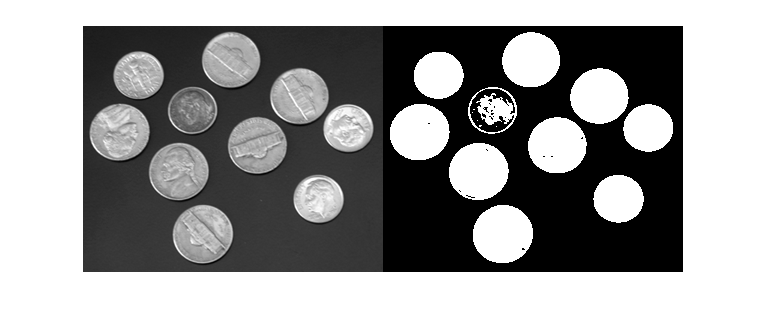

## Part B: Image Thresholding

When applied to arrays, logical operators like `<` and `>` generate arrays of the same size that contain logical values `1` (`true`) or `0` (`false`). You can use logical operators to threshold the intensity values of a grayscale image, creating a binary image.  You can identify a better cutoff value by looking at the image's intensity histogram.  

The following is how the function is used:

%B = g > thresh;

**Instructions:**  Do not edit the first code box.  This code loads an image, converts it to grayscale, and adjusts the contrast.  In the second code box, create a binary image by thresholding the greyscale image at half the maximum possible intensity (the maximum intensity is 255).

image = imread("/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/Receipt_Example.jpg");
greyscale = im2gray(image);
greyscaleAdj = imadjust(greyscale);
imshow(greyscaleAdj)
 

binaryImage = greyscaleAdj > 255/2;
imshow(binaryImage)
 

That didn't exactly yield that results we want.  The thresholding technique that we employed seemed to cause the receipt to be a little washed.  To identify a better cutoff value, I will plot the images intensity histogram.  Threshold the image slightly below the peak of the plotted histogram. 

**Instructions:** Histogram of the intensity values is plotted. Threshold the image slightly below the peak of the plotted histogram so that the thresholded image is less washed.

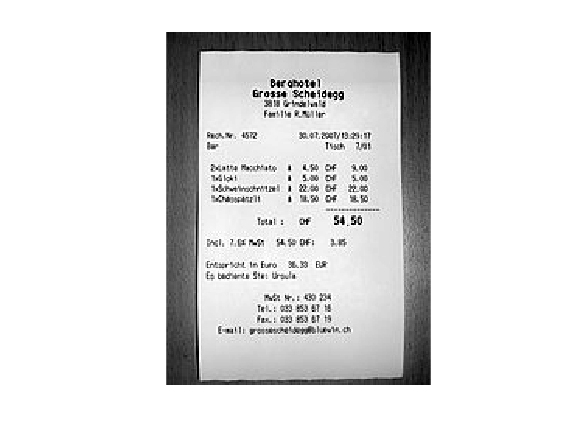

imhist(greyscaleAdj)

binaryImage = greyscaleAdj > 170;
imshow(binaryImage)
 

The goal is to create an algorithm that can process any of the images we want automatically. Unfortunately, receipt images taken in different lighting conditions have varied contrast and require different thresholds. Manually identifying a threshold using the intensity histogram works but is impractical for thousands of images. To automate the threshold selection process, you can use the `imbinarize` function, which calculates the "best" threshold for the image.

The following is how the function is used:

%gBinary = imbinarize(g);

**Instructions:** Do not edit the first code box.  This code loads an image, converts it to grayscale, and adjusts the contrast. Practice using the imbinarize function to automate the threshold selection process.

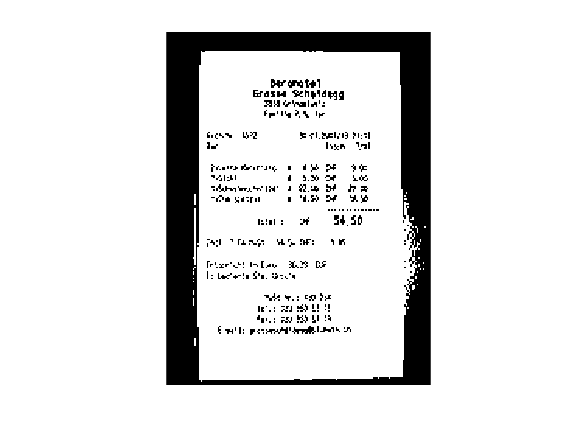

image = imread("/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/Receipt_Example.jpg");

greyscale = im2gray(image);
greyscaleAdj = imadjust(greyscale);
imshow(greyscaleAdj)
 

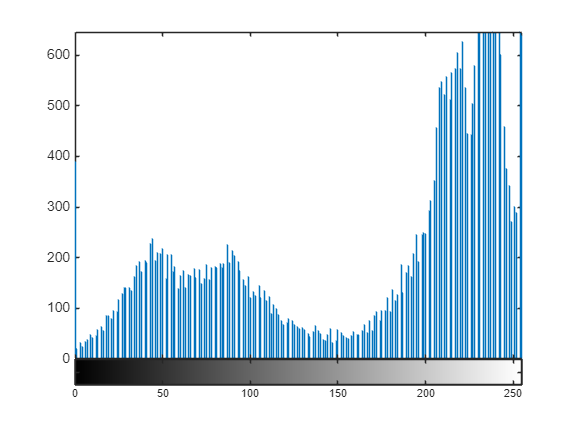

binaryImage = imbinarize(greyscaleAdj);

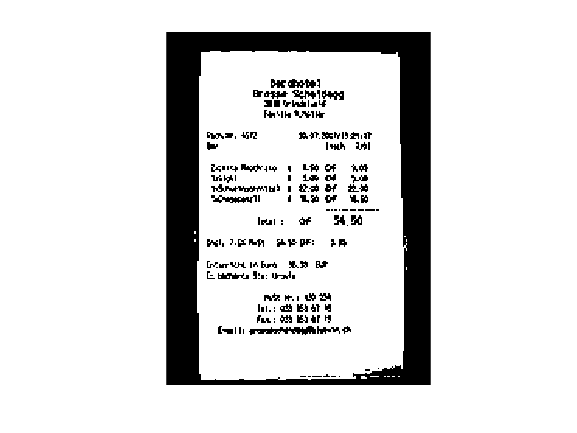

imshow(binaryImage)
 

## 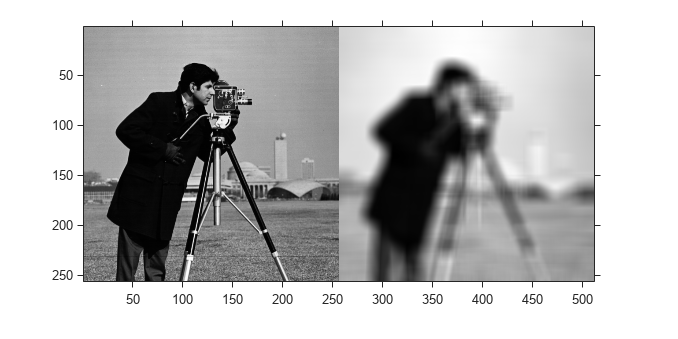

## Part C: Preprocessing and Postprocessing Techniques

Images taken in low light often become noisy due to the increase in camera sensitivity required to capture the image. This noise can interfere with receipt identification by polluting regions in the binarized image. To reduce the impact of this noise on the binary image, you can preprocess the image with an averaging filter. You can apply a filter `F` to an image `I` by using the `imfilter` function.

The following is how the function is used:

%F = fspecial("average",n)

**Instructions:** Use the `fspecial` function to create an *n*-by-*n* averaging filter and apply it to the greyscale adjusted image from before.

F = fspecial("average",2)
Ifltr = imfilter(greyscaleAdj,F);
 

Now that you have filtered the image, we can binarize it: 

binaryImage_smooth = imbinarize(Ifltr,"adaptive","ForegroundPolarity","dark");

imshow(binaryImage_smooth)
 

Did the filter reduce the amount of noise in the binary image?

## Part D: Image Processing Examples

### Example 1 (simple): Identifying Pennies

This MATLAB program takes an input image containing pennies and employs a thresholding technique to estimate the number of pennies present. It prompts the user to input the filename of the image. Then, it reads the image and compares the intensity of the red and blue color channels for each pixel. If the red channel intensity exceeds the blue channel intensity by a certain threshold, the program marks that pixel as part of a potential penny in a binary mask. After processing the entire image, it estimates the number of pennies based on the count of identified regions in the binary mask, assuming an average of 1800 pixels per penny. Finally, the program displays the original image alongside the binary mask for visual inspection.  To test this programming, try input any one of the following filenames: Penny_Alpha.png, Penny_Bravo.png, and Penny_Charlie.png.

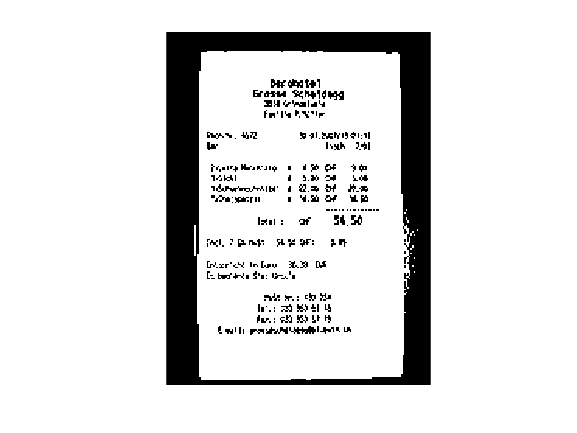

% Clear the command window and workspace
clc; 
clear;


% Prompt the user to enter the filename of the image
%for this input you have to enter the filepath in the command window
%for example you can copy and paste "/MATLAB Drive/MATLAB - Section 06
%(Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part
%1/Receipt_Example.jpg" into the command window below for the receipt
%example image
filename = input('Enter image name: ','s');

% Read the input image from the specified filename

F =     0.2500    0.2500
    0.2500    0.2500


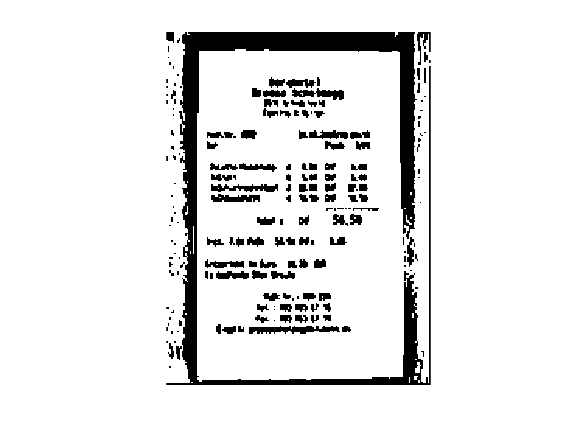

image = imread(filename);

% Get the dimensions of the input image: height, width, and number of color channels
[height, width, colors] = size(image); 

% Create a binary mask to identify regions of interest (in this case, potential pennies)

binary = false(height, width);

% Initialize a counter to keep track of the number of identified pennies
count = 0; 

% Iterate through each pixel in the image
for row = 1:1:height
    for col = 1:1:width
        
        % Extract the color values (red, green, blue) of the current pixel
        red = image(row, col, 1);
        green = image(row, col, 2);
        blue = image(row, col, 3); 
        
        % Check if the red channel intensity is significantly higher than the blue channel intensity
        if red > blue + 50
            % Set the corresponding pixel in the binary mask to 1 (white)
            binary(row, col) = 1;
            % Increment the penny count
            count = count + 1;
        end

    end
end

% Estimate the number of pennies based on the count (assuming an average of 1800 pixels per penny)
count = round(count / 1800);

% Display the estimated number of pennies
fprintf('Number of pennies: %d\n', count)

% Display the original image and the binary mask side by side for visual comparison
figure()
imshowpair(image, binary, 'montage')
 

### Example 2 (Advanced): Identifying images of celebrities

This MATLAB program is designed for image identification of three celebrities: Bruno Mars, Elon Musk, and Selena Gomez. It begins by loading a dataset containing images of these celebrities from a specified folder structure. The dataset is then split into training and validation sets, with 7 images per class reserved for validation. Next, the pre-trained GoogLeNet model, renowned for image recognition tasks, is loaded. The program analyzes the architecture of the GoogLeNet model and modifies it by replacing the final layers with new fully connected and classification layers to adapt it to the specific task of identifying the three celebrities. Data augmentation techniques are applied to enrich the training data, and the modified model is trained using augmented training data and specified training option.  To test this program, download the image identification test function from canvas and test the following images: image1.jpg, image2.jpg, and image3.png.

%name of the folder containing the subfolders of images
folder_name = "/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/My_Dataset"
% Load the dataset containing images of faces from the specified folder structure
Dataset = imageDatastore(folder_name, "IncludeSubfolders", true, "LabelSource", "foldernames");


Number of pennies: 6


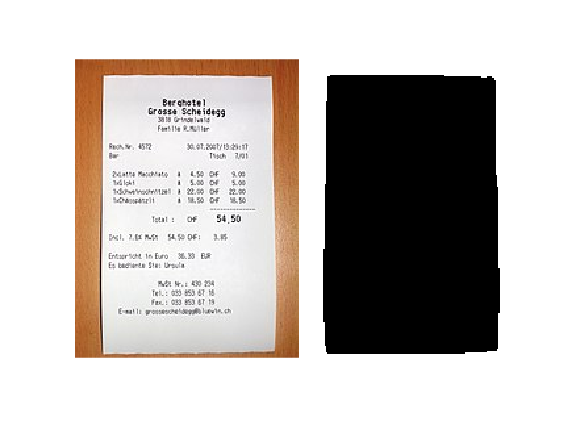

% Split the dataset into training and validation sets, ensuring 7 images per class for validation
[Training_Dataset, Validation_Dataset] = splitEachLabel(Dataset, 7.0);

% Load the pre-trained GoogLeNet model, a deep convolutional neural network renowned for image recognition tasks

net = googlenet; 

% Display the architecture of the GoogLeNet model to understand its structure and layers
analyzeNetwork(net);

% Obtain the input size of the first layer of the GoogLeNet model

folder_name = "/MATLAB Drive/MATLAB - Section 06 (Teacher - File Share)/Section 06 - Part 1 - Image Processing/Data - Part 1/My_Dataset"

Input_Layer_size = net.Layers(1).InputSize;

% Create a layer graph to visualize and modify the network architecture
Layer_graph = layerGraph(net);

% Extract the feature learner and output classifier layers from GoogLeNet
Feature_Learner = net.Layers(142);
Output_Classifer = net.Layers(144);

% Determine the number of classes in the training dataset for configuring the final layers
Number_of_classes = numel(categories(Training_Dataset.Labels));

% Define a new fully connected layer to adapt the model to the specific classification task
New_Feature_Learner = fullyConnectedLayer(Number_of_classes, ...
    'Name', 'Facial Feature Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

% Define a new classification layer to match the number of classes in the dataset
New_Classifier_Layer = classificationLayer('Name', 'Face Classifier');

% Replace the original feature learner and output classifier layers in the network graph with the new ones
Layer_graph = replaceLayer(Layer_graph, Feature_Learner.Name, New_Feature_Learner);
Layer_graph = replaceLayer(Layer_graph, Output_Classifer.Name, New_Classifier_Layer); 

% Visualize the modified network architecture after layer replacement
analyzeNetwork(Layer_graph)

% Define ranges for pixel and scale adjustments for data augmentation to enrich training data
Pixel_Range = [-30 30];
Scale_Range = [0.9 1.1];

% Create an image data augmenter with specified augmentation techniques for robust training
Image_Augmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',Pixel_Range, ...
    'RandYTranslation',Pixel_Range, ...
    'RandXScale', Scale_Range, ...
    'RandYScale', Scale_Range);

% Create augmented image datastores for both training and validation datasets with data augmentation
Augmented_Training_Image = augmentedImageDatastore(Input_Layer_size(1:2), Training_Dataset, ...
    'DataAugmentation', Image_Augmenter); 
Augmented_Validation_Image = augmentedImageDatastore(Input_Layer_size(1:2), Validation_Dataset); 

% Define minibatch size and validation frequency for training options
Size_of_Minibatch = 5;
Validation_Frequency = floor(numel(Augmented_Training_Image.Files)/Size_of_Minibatch);

% Specify training options including optimizer, learning rate, etc. for model training
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize',Size_of_Minibatch, ...
    'MaxEpochs', 6, ...
    'InitialLearnRate', 3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData', Augmented_Validation_Image, ...
    'ValidationFrequency', Validation_Frequency, ...
    'Verbose',false, ...
    'Plot','training-progress');

% Train the modified GoogLeNet model using augmented training data and specified training options
net = trainNetwork(Augmented_Training_Image, Layer_graph, Training_Options);

  %this may take more time to run than usual and another window will open